% openExample('daq/CharacterizeLEDwADALM1000Example')
% openExample('daq/EstimateTransferFunctionwADALM1000Example')

dev = daqlist

Unable to detect 'ni' hardware:
National Instruments NI-DAQmx driver is either not installed or the installed version is not supported.
Use the Windows Control Panel to uninstall any existing NI-DAQmx driver listed under 'National Instruments Software'.
Then, open the Add-On Explorer to install the Data Acquisition Toolbox Support Package for 
National Instruments NI-DAQmx Devices.



dev = 1×5 table
    VendorID    DeviceID              Description                 Model             DeviceInfo      
    ________    ________    _______________________________    ___________    ______________________

     "adi"       "SMU1"     "Analog Devices Inc. ADALM1000"    "ADALM1000"    1×1 daq.adi.DeviceInfo


dev{1,"DeviceInfo"}

ans = adi: Analog Devices Inc. ADALM1000 (Device ID: 'SMU1')
   Analog input supports:
      0 to +5.0 Volts,-0.20 to +0.20 A ranges
      Rates from 100000.0 to 100000.0 scans/sec
      2 channels ('A','B')
      'Voltage','Current' measurement types
   
   Analog output supports:
      0 to +5.0 Volts,-0.20 to +0.20 A ranges
      Rates from 100000.0 to 100000.0 scans/sec
      2 channels ('A','B')
      'Voltage','Current' measurement types
   

Properties, Methods, Events



d = daq("adi")

d = DataAcquisition using Analog Devices Inc. hardware:

                     Running: 0
                        Rate: 100000
           NumScansAvailable: 0
            NumScansAcquired: 0
              NumScansQueued: 0
    NumScansOutputByHardware: 0
                   RateLimit: []

Show channels
Show properties and methods



addoutput(d,"SMU1","A","Voltage")

Unable to add channel 'A' more than once.

addinput(d,"SMU1","A","Current")

addoutput(d,"SMU1","B","Voltage")

Unable to add channel 'B' more than once.

normErr = -1;
errThreshold = 0.001;
numPointForLine = numel(v) - 10;
while 

v = linspace(0,5,250)';
i = readwrite(d,v,"OutputFormat","Matrix");

Specify scan data as an MxN double matrix, where M is the number of scans and N is the number of output channels.

% d.Channels

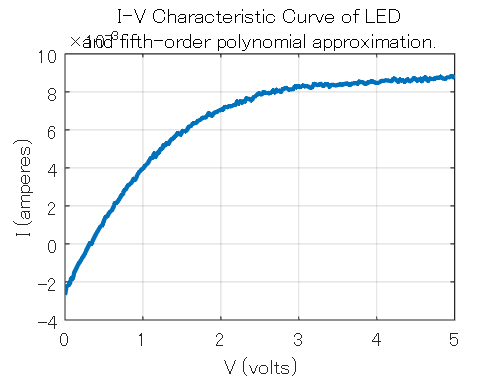

% % Plot the measured data.
plot(v,i,'LineWidth',2);
hold on;
grid on;
ylabel('I (amperes)');
xlabel('V (volts)');
title({'I-V Characteristic Curve of LED';'and fifth-order polynomial approximation.'});

% write(d,0);
% close
% clear d